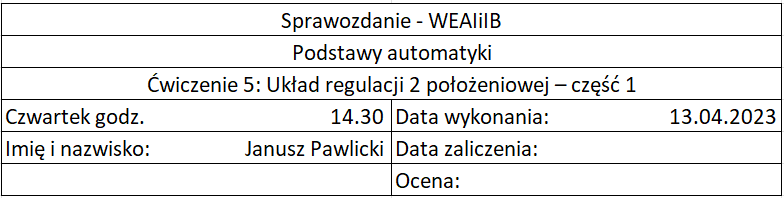

## 1. Cel ćwiczenia

Celem ćwiczenia jest zapoznanie się z działaniem i właściwościami układu regulacji II położeniowej (przekaźnikowej), który jest najprostszym układem regulacji stosowanym w praktyce. Dodatkowo podczas wykonania ćwiczenia należy się zapoznać z środowiskiem SIMULINK, będącym częścią MATLABA pozwalającą na modelowanie systemów dynamicznych z użyciem schematów blokowych.

## 2. Wstęp

Rozważamy dwa układy regulacji:

### a) Obiekt statyczny

   
$$G_1 \left(s\right)=\frac{e^{-\tau_1 s} }{T_1 s+1}$$


### b) Obiekt astatyczny


$$G_2 \left(s\right)=\frac{e^{-\tau_2 s} }{T_2 s}$$


Gdzie $\tau$ oraz $T_{1,2}$ to czas martwy oraz stała czasowa obiektu (1) lub czas całkowania obiektu (2). Parametry te podczas realizacji ćwiczenia będą zmieniane w celu pokazania ich wypływu na działanie układu regulacji.

## 3. Przebieg ćwiczenia

### Obiekt statyczny

SP = 0.5;
h = 0.05;
T = 45;
tau = 22;

### 3.1 Analiza wpływu szerokości histerezy regulatora h.

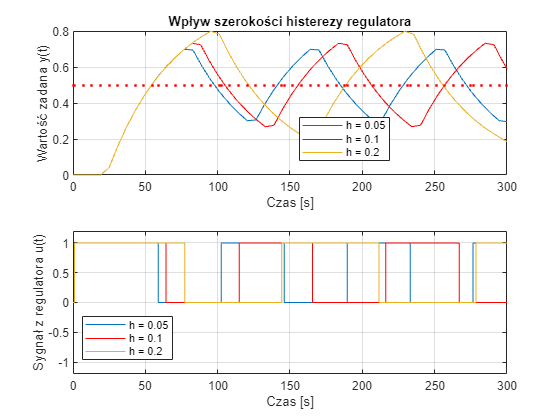

out1 = sim("ukl_reg_I.slx");
y1 = out1.y;
u1 = out1.u;
h = 0.1;
out2 = sim("ukl_reg_I.slx");
y2 = out2.y;
u2 = out2.u;
h = 0.2;
out3 = sim("ukl_reg_I.slx");
y3 = out3.y;
u3 = out3.u;

figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, 'r.')
title("Wpływ szerokości histerezy regulatora")
legend("h = 0.05", "h = 0.1", "h = 0.2", "Location", "best")
grid
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("h = 0.05", "h = 0.1", "h = 0.2", "Location", "best")
xlabel('Czas [s]')
grid
ylabel('Sygnał z regulatora u(t)')
axis([0, 300, -1.2, 1.2])

h = 0.05;

### 3.1 Analiza wpływu wartości opóźnienia obiektu $\tau$.

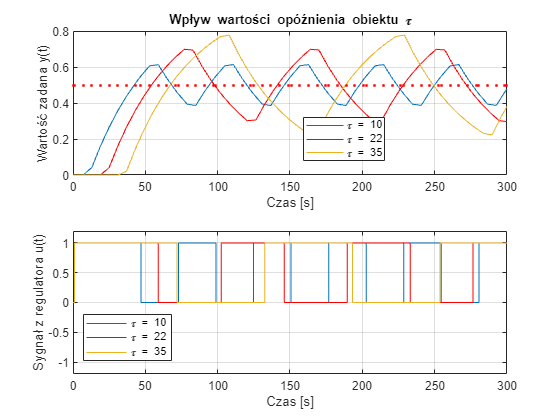

tau = 10;
out1 = sim("ukl_reg_I.slx");
y1 = out1.y;
u1 = out1.u;
tau = 22;
out2 = sim("ukl_reg_I.slx");
y2 = out2.y;
u2 = out2.u;
tau = 35;
out3 = sim("ukl_reg_I.slx");
y3 = out3.y;
u3 = out3.u;

figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, 'r.')
title("Wpływ wartości opóźnienia obiektu \tau")
legend("\tau = 10", "\tau = 22", "\tau = 35", "Location", "best")
grid
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("\tau = 10", "\tau = 22", "\tau = 35", "Location", "best")
xlabel('Czas [s]')
grid
ylabel('Sygnał z regulatora u(t)')
axis([0, 300, -1.2, 1.2])


tau = 22;

### 3.2 Analiza wpływu wartości opóźnienia obiektu T.

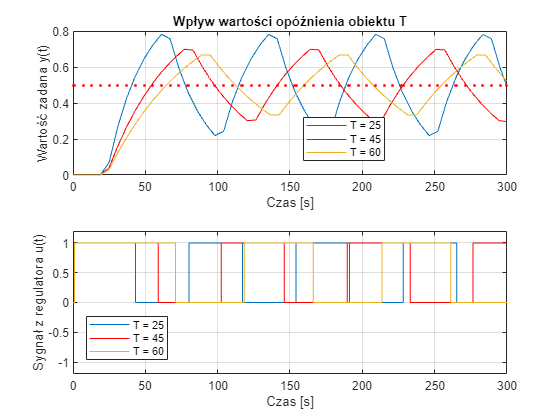

T = 25;
out1 = sim("ukl_reg_I.slx");
y1 = out1.y;
u1 = out1.u;
T = 45;
out2 = sim("ukl_reg_I.slx");
y2 = out2.y;
u2 = out2.u;
T = 60;
out3 = sim("ukl_reg_I.slx");
y3 = out3.y;
u3 = out3.u;

figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, 'r.')
title("Wpływ wartości opóźnienia obiektu T")
legend("T = 25", "T = 45", "T = 60", "Location", "best")
grid
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("T = 25", "T = 45", "T = 60", "Location", "best")
xlabel('Czas [s]')
grid
ylabel('Sygnał z regulatora u(t)')
axis([0, 300, -1.2, 1.2])


T = 45;

### 3.3 Analiza wpływu wartości zadanej SP.

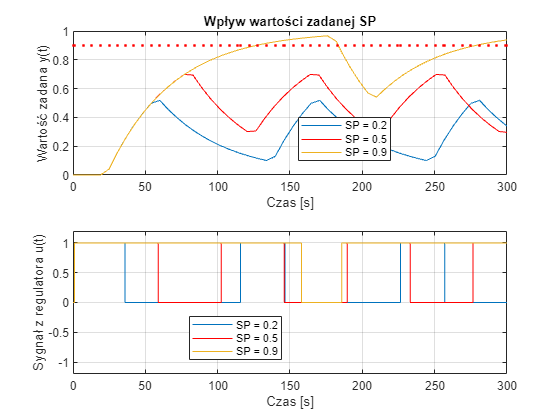

SP = 0.2;
out1 = sim("ukl_reg_I.slx");
y1 = out1.y;
u1 = out1.u;
SP = 0.5;
out2 = sim("ukl_reg_I.slx");
y2 = out2.y;
u2 = out2.u;
SP = 0.9;
out3 = sim("ukl_reg_I.slx");
y3 = out3.y;
u3 = out3.u;

figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, 'r.')
title("Wpływ wartości zadanej SP")
legend("SP = 0.2", "SP = 0.5", "SP = 0.9", "Location", "best")
grid
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("SP = 0.2", "SP = 0.5", "SP = 0.9", "Location", "best")
xlabel('Czas [s]')
grid
ylabel('Sygnał z regulatora u(t)')
axis([0, 300, -1.2, 1.2])


SP = 0.5;

### Obiekt astatyczny

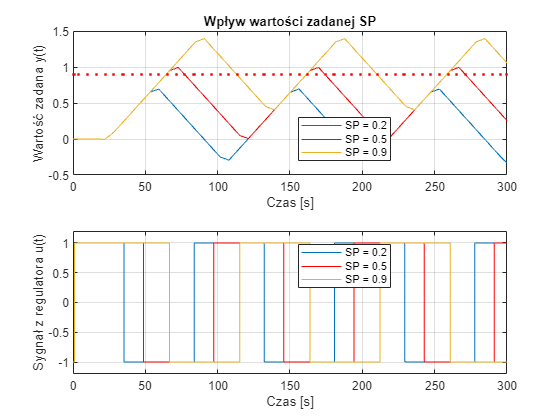

SP = 0.2;
out1 = sim("ukl_reg_I.slx");
y1 = out1.y;
u1 = out1.u;
SP = 0.5;
out2 = sim("ukl_reg_I.slx");
y2 = out2.y;
u2 = out2.u;
SP = 0.9;
out3 = sim("ukl_reg_I.slx");
y3 = out3.y;
u3 = out3.u;

figure
subplot(2, 1, 1)
plot(y1.time, y1.signals.values, y2.time, y2.signals.values, 'r', y3.time, y3.signals.values, y1.time, SP, 'r.')
title("Wpływ wartości zadanej SP")
legend("SP = 0.2", "SP = 0.5", "SP = 0.9", "Location", "best")
grid
xlabel("Czas [s]")
ylabel("Wartość zadana y(t)")
subplot(2, 1, 2)
plot(u1.time, u1.signals.values, u2.time, u2.signals.values, 'r', u3.time, u3.signals.values)
legend("SP = 0.2", "SP = 0.5", "SP = 0.9", "Location", "best")
xlabel('Czas [s]')
grid
ylabel('Sygnał z regulatora u(t)')
axis([0, 300, -1.2, 1.2])


SP = 0.5;

## 4. Wnioski

Zwiększając szerokość histerezy zwiększa się okres sygnału z regulatora oraz sygnału wyjściowego, którego ponadto amplituda rośnie.

Zwiększając opóźnienie opóźnienie układ osiąga większe wartości zadane. Dla małych opóźnień oscyluje z większą częstotliwością, wokół wartości zadanej, a amplituda wahań jest mniejsza.

Zwiększając stałą czasową powodujemy efekt przeciwny do zwiększenia szerokości histerezy lub opóźnienia. Zmniejsza się częstotliwość oscylacji i ich amplituda.

Zmienianie wartości zadanej wpływ na zmianę czasów narastania oraz opadania wartości sygnału na wyjściu. Zmniejszając wartość zadaną SP czas opadania wydłuża się, natomiast zwiększając ją rośnie czas narastania.

Dla obiektu astatycznego jedyną różnicą jest pierwsze wlączenie się regulatora, które następuje później, wraz ze wzrostem SP. Zmiana wartości zadanej więc powoduje znaczne przesunięcie wartości zadanych w pionie. 